% Multivariate Gaussian: 

% X = N x D matrix (each Xi ~ N(mu_i, sigma_i)
% mu = D-dimensional mean vector
% sigma = D x D covariance matrix

%Evaluate using mvnpdf(X, MU, SIGMA)

% (a) Evaluate multivariate gaussian pdf with: 
mu = [0, 0]; % 1 x D
sigma = [1 0.8; 0.8 1]; % D x D covariance matrix
x = [1,1]; % N x D data point (so one observation since N = 1)

mvnpdf(x, mu, sigma)

ans =    0.152192821710411


% (pre (b)) step: meaning of meshgrid: 
% Meshgrid replicates first vector along rows of a matrix
% and replicates second vector along cols of a matrix.
x = 1:3;
y = 1:5;
[X, Y] = meshgrid(x, y)

X =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


Y =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5



% Meaning of reshape: 
mat = [1,2,3,4; 5,6,7,8; 9,10,11,12; 0,3,2,5]

mat =      1     2     3     4
     5     6     7     8
     9    10    11    12
     0     3     2     5


size(mat)

ans =      4     4


reshape(mat, 8, 2)  %reshapes by stacking columns

ans =      1     3
     5     7
     9    11
     0     2
     2     4
     6     8
    10    12
     3     5


% until the dimensions match. 

% (b) contour plot of multivariate Gaussian
% using meshgrid, reshape, and contour
x1 = linspace(-5,5)

x1 =   -5.000000000000000  -4.898989898989899  -4.797979797979798  -4.696969696969697  -4.595959595959596  -4.494949494949495  -4.393939393939394  -4.292929292929293  -4.191919191919192  -4.090909090909091  -3.989898989898990  -3.888888888888889  -3.787878787878788  -3.686868686868687  -3.585858585858586  -3.484848484848485  -3.383838383838384  -3.282828282828283  -3.181818181818182  -3.080808080808081  -2.979797979797980  -2.878787878787879  -2.777777777777778  -2.676767676767677  -2.575757575757576  -2.474747474747475  -2.373737373737374  -2.272727272727273  -2.171717171717172  -2.070707070707070  -1.969696969696970  -1.868686868686869  -1.767676767676768  -1.666666666666667  -1.565656565656566  -1.464646464646465  -1.363636363636364  -1.262626262626263  -1.161616161616162  -1.060606060606061  -0.959595959595959  -0.858585858585859  -0.757575757575758  -0.656565656565657  -0.555555555555555  -0.454545454545454  -0.353535353535354  -0.252525252525253  -0.151515151515151  -0.0505050505

x2 = x1;
len = length(x1)

len =    100


% meshgrid: replicates x1 values along rows to make
% a matrix and replciates x2 along cols to make a matrix.
[X1, X2] = meshgrid(x1, x2)

X1 =   -5.000000000000000  -4.898989898989899  -4.797979797979798  -4.696969696969697  -4.595959595959596  -4.494949494949495  -4.393939393939394  -4.292929292929293  -4.191919191919192  -4.090909090909091  -3.989898989898990  -3.888888888888889  -3.787878787878788  -3.686868686868687  -3.585858585858586  -3.484848484848485  -3.383838383838384  -3.282828282828283  -3.181818181818182  -3.080808080808081  -2.979797979797980  -2.878787878787879  -2.777777777777778  -2.676767676767677  -2.575757575757576  -2.474747474747475  -2.373737373737374  -2.272727272727273  -2.171717171717172  -2.070707070707070  -1.969696969696970  -1.868686868686869  -1.767676767676768  -1.666666666666667  -1.565656565656566  -1.464646464646465  -1.363636363636364  -1.262626262626263  -1.161616161616162  -1.060606060606061  -0.959595959595959  -0.858585858585859  -0.757575757575758  -0.656565656565657  -0.555555555555555  -0.454545454545454  -0.353535353535354  -0.252525252525253  -0.151515151515151  -0.0505050505

X2 =   -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.0000000000

% note: X1(:) means stacking the cols of X1 to form
% a vector out of X1. 
f = mvnpdf([X1(:), X2(:)], mu, sigma)

f =    0.000000246491006
   0.000000321738219
   0.000000408221196
   0.000000503477156
   0.000000603608451
   0.000000703432086
   0.000000796856939
   0.000000877465127
   0.000000939227269
   0.000000977243618
   0.000000988385383
   0.000000971719923
   0.000000928639648
   0.000000862669926
   0.000000778992751
   0.000000683775438
   0.000000583424816
   0.000000483891085
   0.000000390123099
   0.000000305736319
   0.000000232907632
   0.000000172469272
   0.000000124145523
   0.000000086864378
   0.000000059080436
   0.000000039060427
   0.000000025102768
   0.000000015681859
   0.000000009522803
   0.000000005621127
   0.000000003225324
   0.000000001798931
   0.000000000975320
   0.000000000514009
   0.000000000263321
   0.000000000131127
   0.000000000063473
   0.000000000029866
   0.000000000013660
   0.000000000006073
   0.000000000002625
   0.000000000001103
   0.000000000000450
   0.000000000000179
   0.000000000000069
   0.000000000000026
   0.000000000000009
   0.0000

size(f)

ans =        10000           1


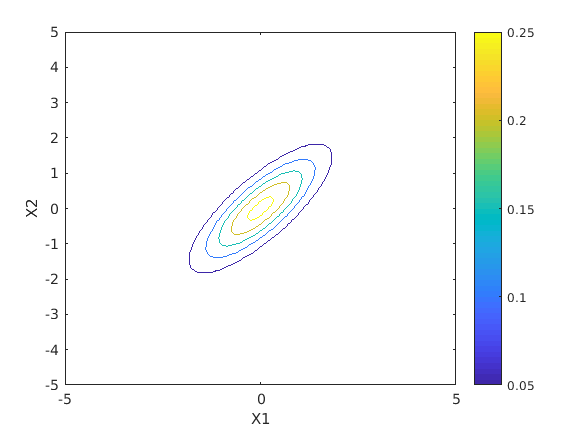

figure(1); clf
%reshapes by stacking columns
% until the dimensions match. 
contour(X1, X2, reshape(f, 100, 100))
xlabel('X1');
ylabel('X2');
colorbar

% (c) use MLE mehod to estimate mu and SIGMA from the
% data and overlay a contour plot of the PDF
% with a scatter plot of the data. 

load correlated.dat

X = correlated;
[N, D] = size(X)

N =    100


D =      2



% For a matrix, sum adds up elements in each column
% like a table. 
mu_ML = sum(X) / N 

mu_ML =    0.983145665000000  -0.019142702000000


size(mu_ML) % 1 x D

ans =      1     2


% Equivalent way using for loop: 
mu_ML2 = zeros(1, D); 

for d = 1:D
    mu_ML2(1, d) = sum(X(:,d)) / N;
end
mu_ML2

mu_ML2 =    0.983145665000000  -0.019142702000000


%Matlab way
mu_ML3 = mean(X)

mu_ML3 =    0.983145665000000  -0.019142702000000


% Calculate the covariance matrix (DxD)
V = zeros(D, N);
for i = 1:N
    V(:, i) = X(i, :) - mu_ML;
end
sigma_ML = V * V' ./ N

sigma_ML =    0.487050037864900   0.960567013460527
   0.960567013460527   1.993077532965148


sigma_ML_unbiased = V*V' ./ (N - 1)

sigma_ML_unbiased =    0.491969735217071   0.970269710566189
   0.970269710566189   2.013209629257725


% Another way, vectorizing the above
V_ = (X' - mu_ML'); % transposing each since formula
% requires that X and mu_ML be column vectors
% so we are subtracting: X_DxN - mu_1xD
sigma_ML2 = V_ * V_' ./ N

sigma_ML2 =    0.487050037864900   0.960567013460527
   0.960567013460527   1.993077532965148


% Matlab way
sigma_ML3 = cov(X) % does the unbiased way

sigma_ML3 =    0.491969735217071   0.970269710566189
   0.970269710566189   2.013209629257725


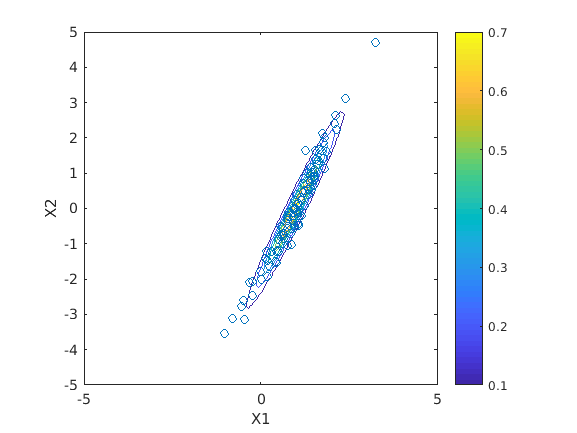

% Make scatter plot of data along with contour plot
figure(1); clf
f = mvnpdf([X1(:), X2(:)], mu_ML, sigma_ML);
contour(X1, X2, reshape(f, 100, 100))
xlabel('X1')
ylabel('X2')
colorbar
hold on
scatter(X(:,1), X(:,2)); 
axis square